ans = 0.0450

ans = 2.7188

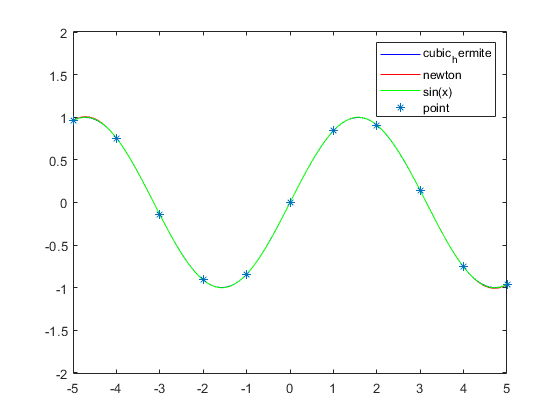

ans = 0.0063

clc,clear;
x=-5:1:5;
y=sin(x);
hermite(x,y)

这里对于写hermite插值的函数进行一些测试

syms x x1 x2 d1 d2 y1 y2;
x1=1;
x2=2;
y1=2;
y2=2;
d1=2;
d2=2;
p=(((x-x2)/(x1-x2))^2)*(1+2*(x-x1)/(x2-x1))*y1+(((x-x1)/(x2-x1))^2)*(1+2*(x-x2)/(x1-x2))*y2+(((x-x2)/(x1-x2))^2)*(x-x1)*d1+(((x-x1)/(x2-x1))^2)*(x-x2)*d2

$$p = 2\,{\left(x-1\right)}^{2}\,\left(x-2\right)+2\,\left(x-1\right)\,{\left(x-2\right)}^{2}+2\,\left(2\,x-1\right)\,{\left(x-2\right)}^{2}-2\,\left(2\,x-5\right)\,{\left(x-1\right)}^{2}$$

%simplify(p)
p=collect(p)

$$p = 4\,x^{3}-18\,x^{2}+26\,x-10$$

h=sym2poly(p)

h =      4   -18    26   -10


h=cubic_Hermite(-1,1,sin(-1),sin(1),cos(-1),cos(1))

h =    -0.1506         0    0.9921         0


扩展研究

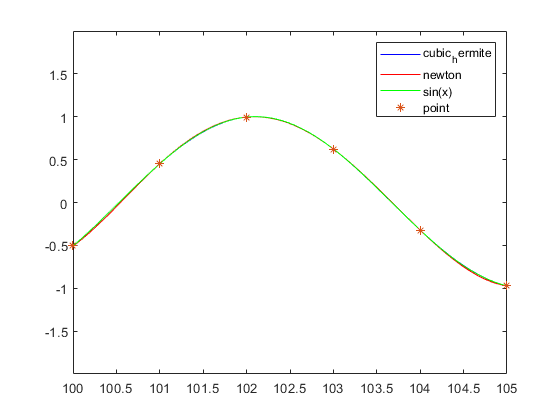

ans = 0.0193

clc,clear;
x=100:1:105;
y=sin(x);
hermite(x,y)

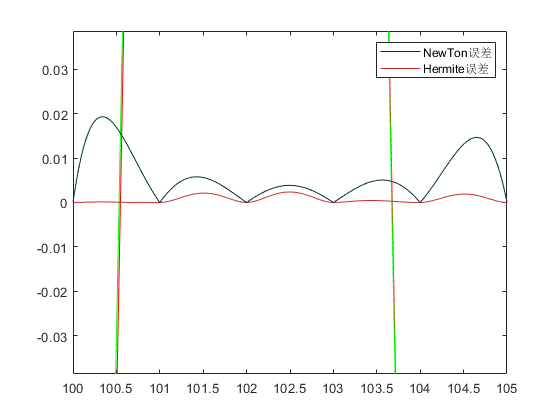

clc,clear;
x=100:1:105;
y=sin(x);
EvaInterp(x,y)

现在考察插值的误差

clc,clear;

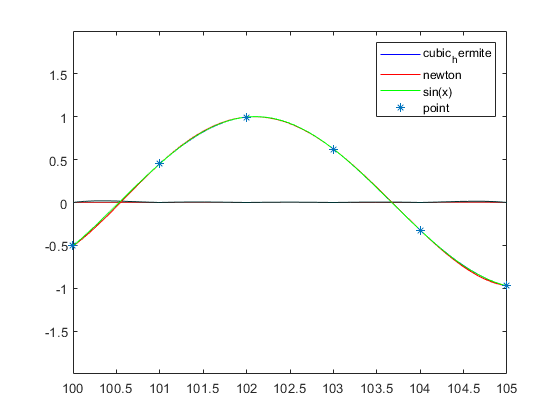

ans = 0.0193

x=100:1:105;
y=sin(x);
hermite(x,y)

EvaInterp(x,y)

clc,clear;
x=-5:1:5;
y=sin(x);
hermite(x,y)

ans = 0.0063

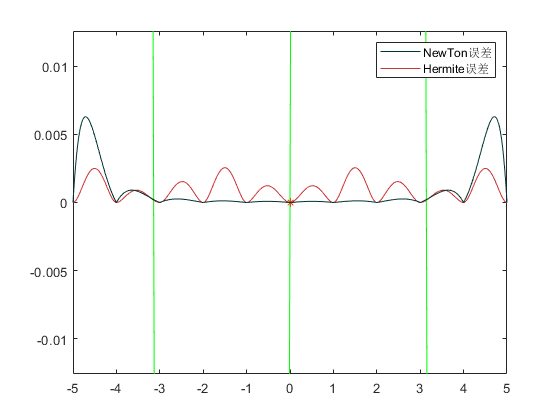

EvaInterp(x,y)

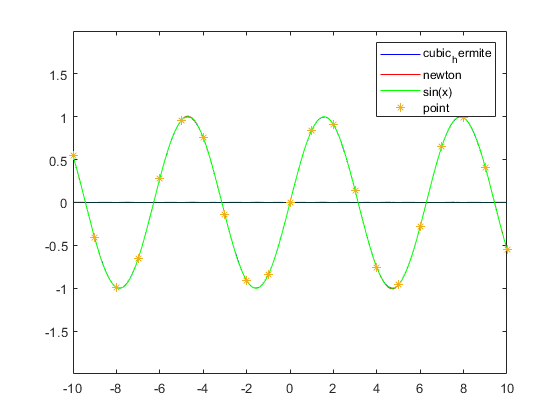

ans = 0.0017

clc,clear;
x=-10:1:10;
y=sin(x);
hermite(x,y)

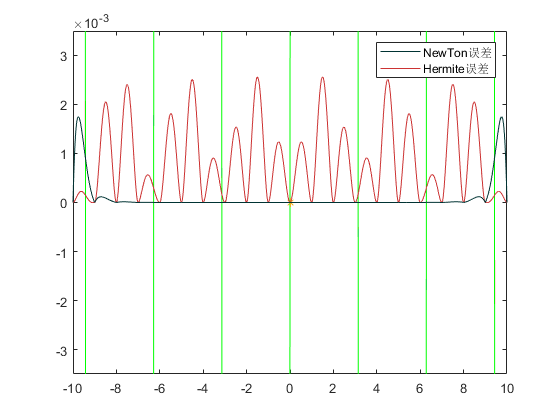

EvaInterp(x,y)

maxy = 0

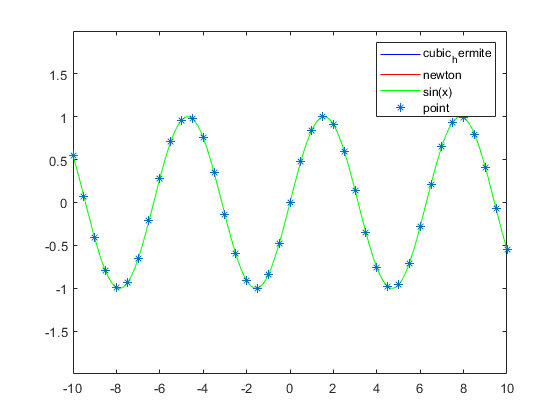

clc,clear;
x=-10:0.5:10;
y=sin(x);
hermite(x,y)

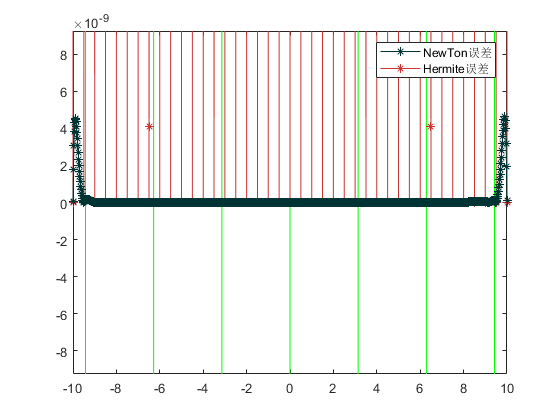

EvaInterp(x,y)